% basePath = '../../../Data/BZ14_control_crop/';
basePath = 'E:/Cardiac_0629/';

sdata = new_STARMapDataset(basePath, 'useGPU', true);

Pipeline Obj is generated...


sdata = sdata.LoadRawImages('', 'sub_dir', 'position1');

====Loading raw images====
Loading round 1...[time = 4.16 s]
Loading round 2...[time = 3.35 s]
Loading round 3...[time = 3.37 s]
Loading round 4...[time = 3.64 s]
Loading round 5...[time = 3.65 s]
Collapsed to size 1024 by 1024 by 36
Collapsing round 1
Collapsing round 2
Collapsing round 3
Collapsing round 4
Collapsing round 5


sdata = sdata.HistEqualize('Method', "inter_round");

====Histogram Equalization====
Method: inter_round
Equalizing channel 1
Equalizing channel 2
Equalizing channel 3
Equalizing channel 4


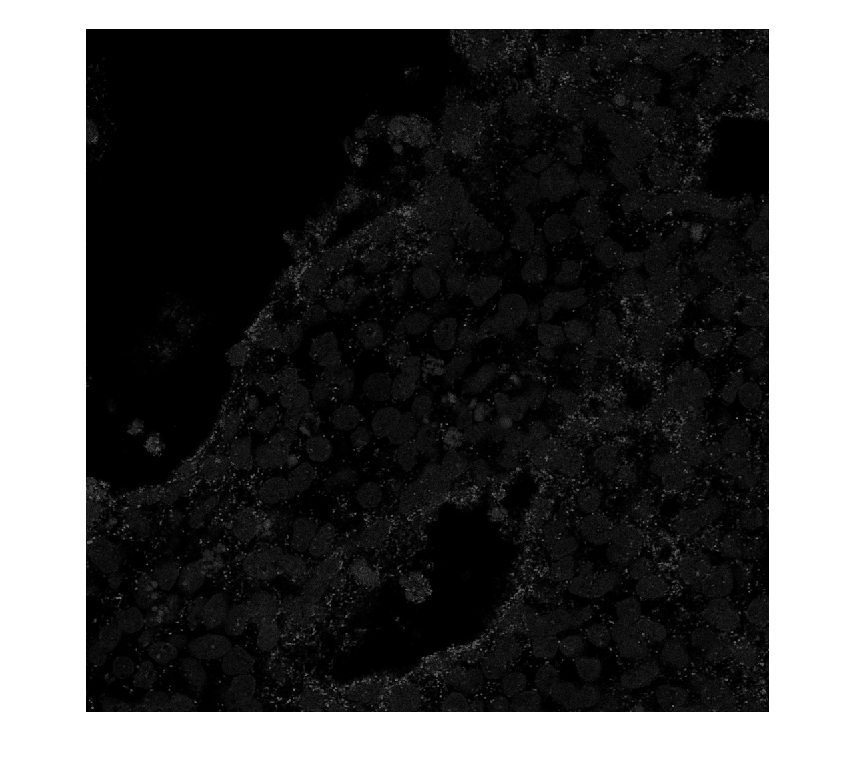

figure
imshow(sdata.rawImages(:,:,1,1,1))


max(sdata.rawImages(:,:,1,1,1), [], 'all')

ans = uint8
122

% sdata.rawImages = gpuArray(sdata.rawImages);
% sdata = sdata.SwapChannels;
sdata = sdata.LoadCodebook;

====Load Codebook====
doReverse: 1


sdata = sdata.MinMaxNormalize;

====Min-Max intensity normalization====
Normalizing Round 1...[time = 1.66 s]
Normalizing Round 2...[time = 0.87 s]
Normalizing Round 3...[time = 0.94 s]
Normalizing Round 4...[time = 0.81 s]
Normalizing Round 5...[time = 0.88 s]


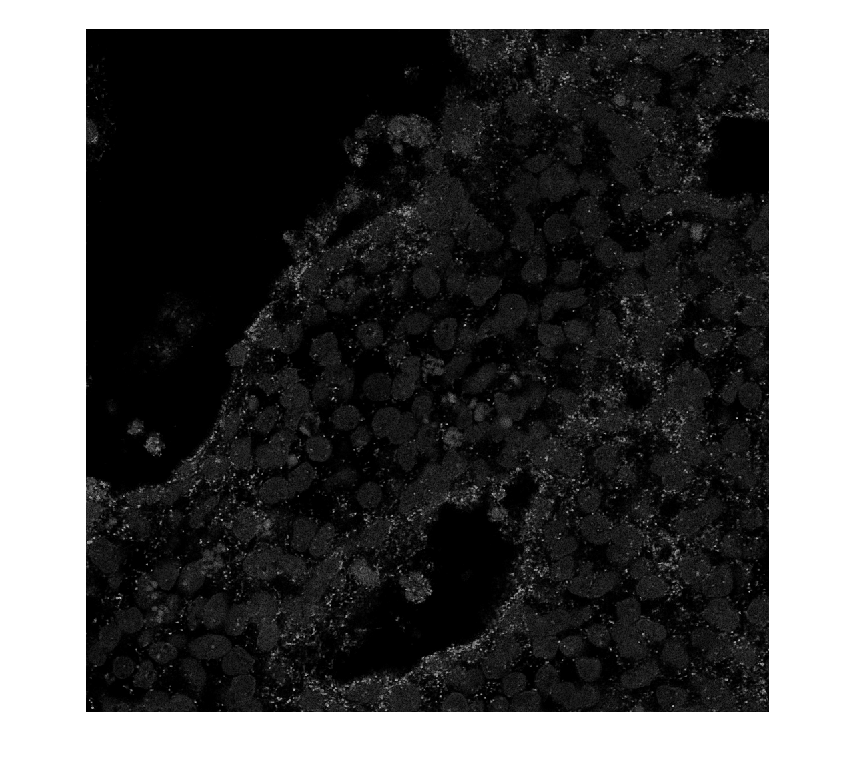

figure
imshow(sdata.rawImages(:,:,1,1,1))


max(sdata.rawImages(:,:,1,1,1), [], 'all')

ans = uint8
194

sdata = sdata.MorphoRecon('Method', "2d_thres", 'radius', 1);

====Morphological Reconstruction====
Method: 2d_thres
Processing Round 1...[time = 4.37 s]
Processing Round 2...[time = 3.78 s]
Processing Round 3...[time = 3.68 s]
Processing Round 4...[time = 3.72 s]
Processing Round 5...[time = 3.62 s]


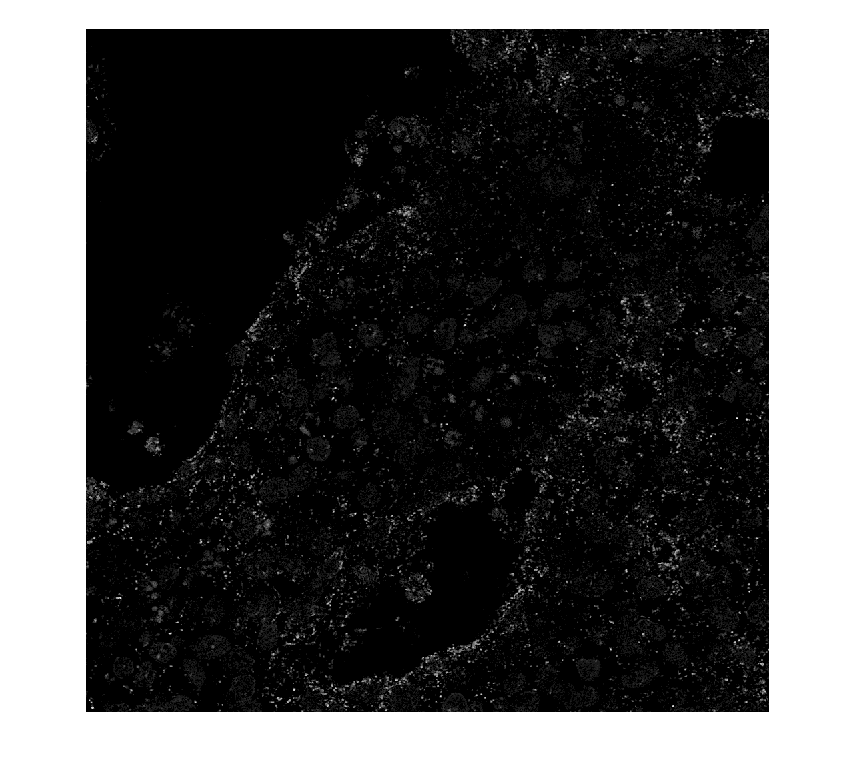

figure
imshow(sdata.rawImages(:,:,1,1,1))


max(sdata.rawImages(:,:,1,1,1), [], 'all')

ans = uint8
255

% sdata = sdata.GlobalRegistration('nblocks', [2 1]);
sdata = sdata.GlobalRegistration;
sdata = sdata.LocalRegistration('Iterations', 5);
% sdata.registeredImages = gather(sdata.registeredImages);

sdata = sdata.SpotFinding('Method', "max3d", 'qualityThreshold', 0.01, ...
    'volumeThreshold', 5, 'barcodeMethod', "iteration", 'showPlots', true);

sdata = sdata.ReadsExtraction('showPlots',false); 
sdata = sdata.ReadsFiltration('showPlots',false);

max_img = max(sdata.registeredImages(:,:,:,:,5), [], 4);
max_img = max(max_img, [], 3);

figure
imshow(max_img)
hold on
plot(sdata.goodSpots(:,1), sdata.goodSpots(:,2), '.', "Color", 'red', "MarkerSize", 2)
hold off

for z=1:36
    figure
    imshow(sdata.rawImages(:,:,z,1,5))
end

se = strel('disk', 6);

for z=1:1
    curr_slice = test_img(:,:,z,1,1);
    figure
    imshow(curr_slice)
    
    curr_slice = im2double(curr_slice);
    curr_max = max(curr_slice, [], 'all');
    curr_min = min(curr_slice, [], 'all');
    curr_slice = (curr_slice - curr_min) ./ (curr_max - curr_min);
    curr_slice = uint8(curr_slice .* 255); %% WARNING
    
    
    marker = imerode(curr_slice, se); % Morphological opening is useful for removing small objects from an image while preserving the shape and size of larger objects in the image
    obr = imreconstruct(marker, curr_slice);
    curr_out = curr_slice - obr;
    figure
    imshow(curr_out)
    %imhist(curr_out)
    max(curr_slice, [], 'all')
    max(obr, [], 'all')
    max(curr_out, [], 'all')
    p = [10 25 50 75];
    prctile(curr_out, p, 'all')
    
    curr_bw = curr_out > 0 & curr_out < 50;
    figure
    imshow(curr_bw)
    
    %mag = curr_out(~curr_bw);
    %histogram(mag)
    
    % 
    curr_out(curr_bw) = 0;
    %
    
    curr_out = im2double(curr_out);
    curr_max = max(curr_out, [], 'all');
    curr_min = min(curr_out, [], 'all');
    curr_out = (curr_out - curr_min) ./ (curr_max - curr_min);
    curr_out = uint8(curr_out .* 255); %% WARNING

    %     curr_out = imsubtract(imadd(curr_out, imtophat(curr_out, se)), imbothat(curr_out, se));
    figure
    %imshow(curr_out)
    imhist(curr_out)
    max(curr_out, [], 'all')
    
    curr_bw = curr_out > 0 & curr_out < 10;
    figure
    imshow(curr_bw)
end

input_img = sdata.gpuImages;
seqTogene = sdata.seqToGene;
quality_factor = 0.01;
volume_threshold = 10;
method = "image";
showPlots = true;
useGPU = true;

goodCodes = str2double(keys(seqTogene));
locations = [];

local_threshold = quality_factor;
% get barcode for each pixel
[base_call_stack, quality_matrix, barcodes] = GetBarcodes(input_img, local_threshold, useGPU);

% get global quailty
base_call_qual = quality_matrix(quality_matrix ~= 0);
base_call_qual = reshape(base_call_qual, 1, numel(base_call_qual));

% get global quailty threshold
quality_threshold = quality_factor * max(quality_matrix, [], 'all');
fprintf('The global quality score threshold for barcode calling is: %4.2f \n', quality_threshold)

if showPlots
    figure
    hold on
    plot(sort(base_call_qual, 'descend'))
    plot(1:numel(base_call_qual), ones(numel(base_call_qual),1) * mean(base_call_qual))
    title('Global barcode quality')
    hold off
end

switch method
    case "iteration"
        
%             % fill missing value
%             for i =1:1
%             base_call_stack(base_call_stack == 0) = NaN;
%             base_call_stack = fillmissing(base_call_stack, 'movmedian', [1 1]);
%             base_call_stack = fillmissing(base_call_stack, 'movmedian', [1 1], 2);
%             base_call_stack = fillmissing(base_call_stack, 'constant', 0);
% 
%             quality_matrix(quality_matrix == 0) = NaN;
%             quality_matrix = fillmissing(quality_matrix, 'movmedian', [1 1]);
%             quality_matrix = fillmissing(quality_matrix, 'movmedian', [1 1], 2);
%             quality_matrix = fillmissing(quality_matrix, 'constant', 0);
%             end

        % iterate through all barcode clusters
        Ncluster = numel(barcodes);
        props = {'Volume'; 'Centroid'};
        % props = {'Volume'; 'Centroid'; 'EquivDiameter'; 'VoxelIdxList'};

        all_volume = []; 
        fprintf('Iterate through clusters...')
        tic;
        % parfor c = 1:Ncluster
        parfor c = 1:numel(goodCodes)

            curr_barcode = goodCodes(c); 
            
            curr_img = zeros(size(base_call_stack)); 
            curr_img(base_call_stack == curr_barcode & quality_matrix > quality_threshold) = 1; % global quality filtration 
            curr_img = logical(curr_img);


            curr_stats = regionprops3(curr_img, props);
            all_volume = [all_volume; curr_stats.Volume]; %% WARNING
            curr_valid_cc = curr_stats(curr_stats.Volume > volume_threshold, "Centroid"); % volume filtration
            curr_valid_cc = int16(table2array(curr_valid_cc));
            if ~isempty(curr_valid_cc)       
                locations = [locations; curr_valid_cc]; %% WARNING
            end
                
        end

        fprintf(sprintf('[time = %.2f s]\n', toc));


        if showPlots
            figure
            histogram(all_volume)
        end

    case "image"
        % NEW
        if useGPU
            base_call_stack = gather(base_call_stack);
        end

        out_stack = zeros(size(base_call_stack));
        se = ones(3);
        
        for z=1:size(base_call_stack,3)
            curr_slice = base_call_stack(:,:,z);
            good_pixels = ismember(curr_slice, goodCodes);
            curr_slice(~good_pixels) = 0;
            
            %bmask = imdilate(curr_slice, se)
            
            %bmask = boundarymask(base_call_stack(:,:,z));
            bmask = imdilate(curr_slice, se) > curr_slice;
            
            base_bw = imbinarize(curr_slice);
            %base_bw = imbinarize(base_call_stack(:,:,z));
            base_bw = imfill(base_bw, 'holes');
            bmask = imcomplement(bmask);
            out_bw = base_bw .* bmask;
            out_stack(:,:,z) = out_bw;
            
            figure             
            imshow(out_bw)
        end

        props = {'Volume'; 'Centroid'};
        out_stack(quality_matrix <= quality_threshold) = 0; % global quality filtration
        %out_stack( (0.9 < quality_matrix) & ( quality_matrix <= 1)) = 0; % test 
        curr_stats = regionprops3(logical(out_stack), props);
        curr_valid_cc = curr_stats(curr_stats.Volume > volume_threshold, "Centroid"); % volume filtration
        curr_valid_cc = int16(table2array(curr_valid_cc));
        if ~isempty(curr_valid_cc)       
            locations = [locations; curr_valid_cc]; %% WARNING
        end

        if showPlots
            figure
            histogram(curr_stats.Volume)

%                 figure
%                 imshow(out_stack(:,:,14))
        end
end

I = zeros(100, 100, 'double');

I(20:30, 20:30) = 1;
I(25:30, 20:28) = 4;
I(20:30, 30:40) = 2;
I(20:30, 40:50) = 3;

I(21:22, 42:44) = 0;
I(25:26, 31:32) = 0;

figure
imshow(I)

se = ones(3);
bmask = imdilate(I, se) > I;
base_bw = imbinarize(I);
base_bw = imfill(base_bw, 'holes');
bmask = imcomplement(bmask);
out_bw = base_bw .* bmask;

figure
imshow(out_bw)